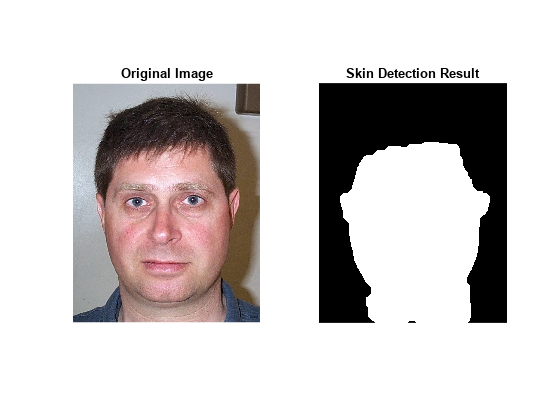

clear
for i = 1:14
    % Load your image
    im = imread("Faces/db1_" + i + ".jpg");
    im = AWB(im, 20);
    im = colorCorrection(im);
    im = AWB(im,0);
    im = contrastStretchColor(im,0,1);
    
       % Convert the RGB image to YCbCr color space
    ycbcrImage = rgb2ycgcr(im);
    
    % Extract the Y, Cb, and Cr channels
    Y = ycbcrImage(:, :, 1);
    Cb = ycbcrImage(:, :, 2);
    Cr = ycbcrImage(:, :, 3);
    
    % Define thresholds for skin color in YCbCr space
    % Trail and Error Values
    Ymin = 0.3;
    Ymax = 0.92;
    Cbmin = 0.3;
    Cbmax = 0.55;
    Crmin = 0.06;
    Crmax = 0.17;

    % Create binary masks for skin regions
    skinMask = Y >= Ymin & Y <= Ymax & Cb >= Cbmin & Cb <= Cbmax & Cr >= Crmin & Cr <= Crmax;
    skinMask = skinMask;
    SE = strel('disk', 6);
    skinMask = imerode(skinMask, SE);
    skinMask = imclose(skinMask, SE);

    SE = strel('disk', 12);
    skinMask = imdilate(skinMask, SE);
    skinMask = imclose(skinMask, SE);

    skinMask = imfill(skinMask, 'holes');
    % Overlay the skin mask on the original image
    outputImage = im;
    outputImage(repmat(~skinMask, [1, 1, 3])) = 0;
    
    % Display the original image and the skin detection result
    subplot(1, 2, 1);
    imshow(im);
    title('Original Image');
    
    subplot(1, 2, 2);
    imshow(skinMask);
    title('Skin Detection Result');

    % Add a pause between figures
    pause(.5)
end

## Contrast strech

function stretchedImage = contrastStretchColor(inputImage, newMinValue, newMaxValue)
    % Get the dimensions of the input image
    [m, n, numChannels] = size(inputImage);
    
    % Initialize the output image with the input image
    stretchedImage = inputImage;

    for channel = 1:numChannels
        % Extract the channel
        channelImage = inputImage(:, :, channel);
        
        % Calculate the minimum and maximum pixel values in the channel
        minValue = min(channelImage(:));
        maxValue = max(channelImage(:));

        % Cast minValue and maxValue to double for consistent data type
        minValue = double(minValue);
        maxValue = double(maxValue);

        % Perform contrast stretching on the channel
        stretchedImage(:, :, channel) = (double(channelImage) - minValue) / (maxValue - minValue) * (newMaxValue - newMinValue) + newMinValue;
    end
end


function skinMask = skinMasker(rgbImage)
   % Convert the RGB image to YCbCr color space
    ycbcrImage = rgb2ycgcr(rgbImage);
    
    % Extract the Y, Cb, and Cr channels
    Y = ycbcrImage(:, :, 1);
    Cb = ycbcrImage(:, :, 2);
    Cr = ycbcrImage(:, :, 3);
    
    % Apply preprocessing to enhance the skin detection:
    % You can use techniques like noise reduction, smoothing, or thresholding.
    
    % Define thresholds for skin color in YCbCr space
    % These thresholds may need adjustment depending on your specific dataset.
    % Ymin = 80;
    % Ymax = 240;
    % Cbmin = 70;
    % Cbmax = 135;
    % Crmin = 125;
    % Crmax = 190;

    Ymin = 0.31;  % Adjust as needed
    Ymax = 0.62;  % Adjust as needed
    Cbmin = 0.27;  % Adjust as needed
    Cbmax = 0.53;  % Adjust as needed
    Crmin = 0.49;  % Adjust as needed
    Crmax = 0.75;  % Adjust as needed

    % Create binary masks for skin regions
    skinMask = Y >= Ymin & Y <= Ymax & Cb >= Cbmin & Cb <= Cbmax & Cr >= Crmin & Cr <= Crmax;
   
end

function ycgcrImage = rgb2ycgcr(rgbImage)
    % Define the conversion matrix for RGB to YCGCR
    conversionMatrix = [0.299 0.587 0.114; -0.1687367 -0.331264 0.5; 0.5 -0.418688 -0.081312];
    
    % Convert the RGB image to YCGCR
    [rows, cols, ~] = size(rgbImage);
    ycgcrImage = zeros(rows, cols, 3);
    
    for i = 1:rows
        for j = 1:cols
            pixel = double(reshape(rgbImage(i, j, :), 3, 1));
            ycgcrPixel = conversionMatrix * pixel;
            ycgcrImage(i, j, :) = ycgcrPixel;
        end
    end

    % Normalize the YCGCR channels
    ycgcrImage(:, :, 2) = ycgcrImage(:, :, 2) + 0.5;
    ycgcrImage = min(max(ycgcrImage, 0), 1);
end